## IE311 - Aula Prática 3

## Compressão em Alcance

**Exercício 1**

O radar emite um pulso modulado em frequência de 1 μs de duração e 100 MHz de banda. A frequência do pulso$f\left(t\right)$ varia linearmente com o tempo, conforme a figura abaixo. A fase do pulso é dada por:


$$\varphi \left(t\right)=2\pi \int f\left(t\right)\mathrm{dt}$$



$$t_o =f^{-1} \left(0\right)\to \varphi \left(t_0 \right)=0$$


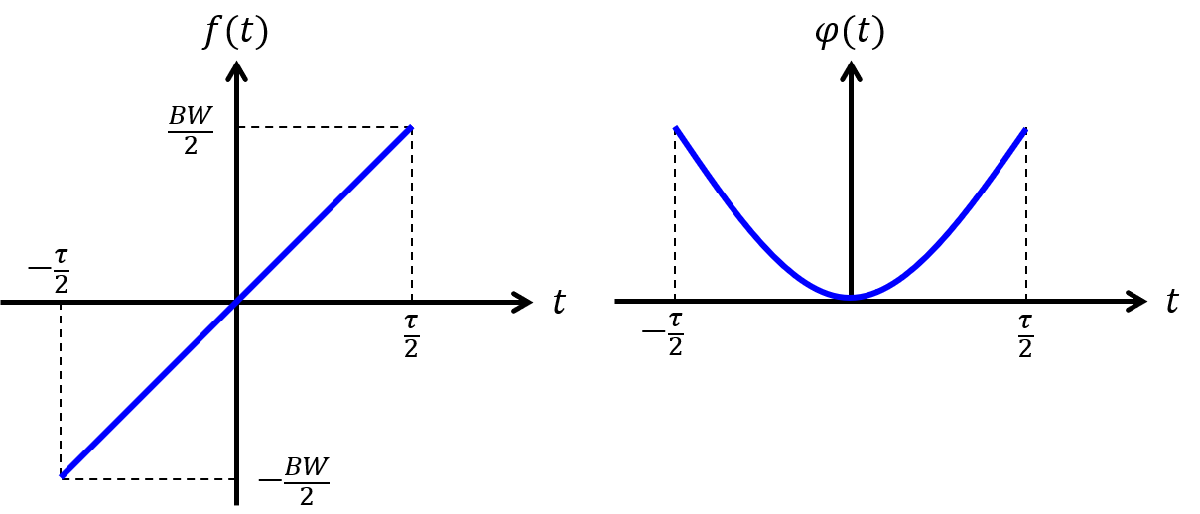

Mostre a parte real e a parte imaginária do pulso, usando uma taxa de amostragem de 120 MHz.

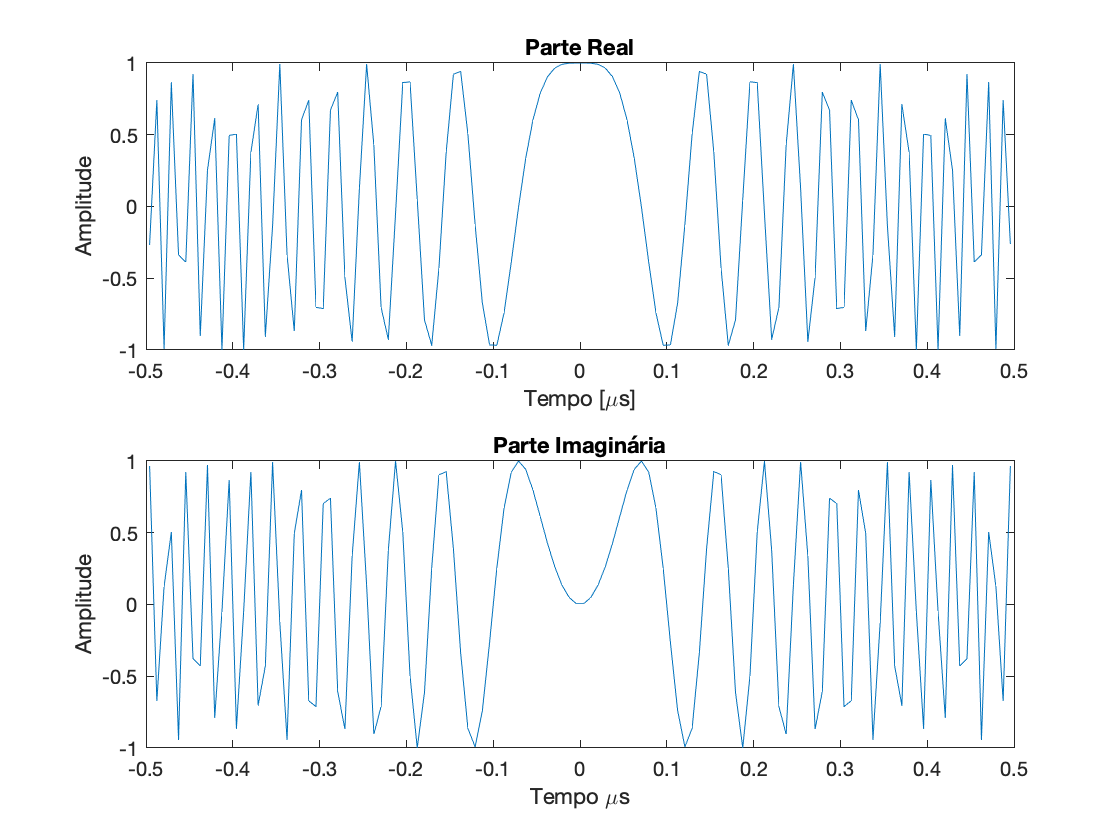

% Escreva seu código aqui
tau = 1e-6;                             %Duração do pulso
BW = 100e6;                             %Banda do pulso
samplingRate = 120e6;                   %Taxa de amostragem

M = fix(tau*samplingRate);              %Número de amostras
t = (-(M-1)/2: (M-1)/2)/samplingRate;

kappa = BW/tau;                         %Inclinação de f(t)
pulsePhase = pi*kappa*t.^2;             %Fase do pulso

chirp_ = exp(1i*pulsePhase);

subplot(2,1,1)
plot(t/1e-6,real(chirp_))
xlabel('Tempo [\mus]')
ylabel('Amplitude')
title('Parte Real')
subplot(2,1,2)

plot(t/1e-6,imag(chirp_))
xlabel('Tempo \mus')
ylabel('Amplitude')
title('Parte Imaginária')

**Exercício 2**

O radar emite um pulso em determinada posição de sua trajetória. Neste instante, a antena do radar "enxerga" um alvo pontual a 370 m de distância (alcance de visada direta), cuja taxa de reflexão é igual a 100. O sinal de retorno é amostrado com uma taxa de 120 MHz. A linha de alcance possui 512 amostras e a primeira delas corresponde a uma distância de 0 m do radar.

**a) **Mostre a linha de alcance de forma que o alvo apareça como uma única amostra, correspondente à melhor aproximação de seu alcance de visada direta, e com amplitude igual a sua taxa de reflexão.

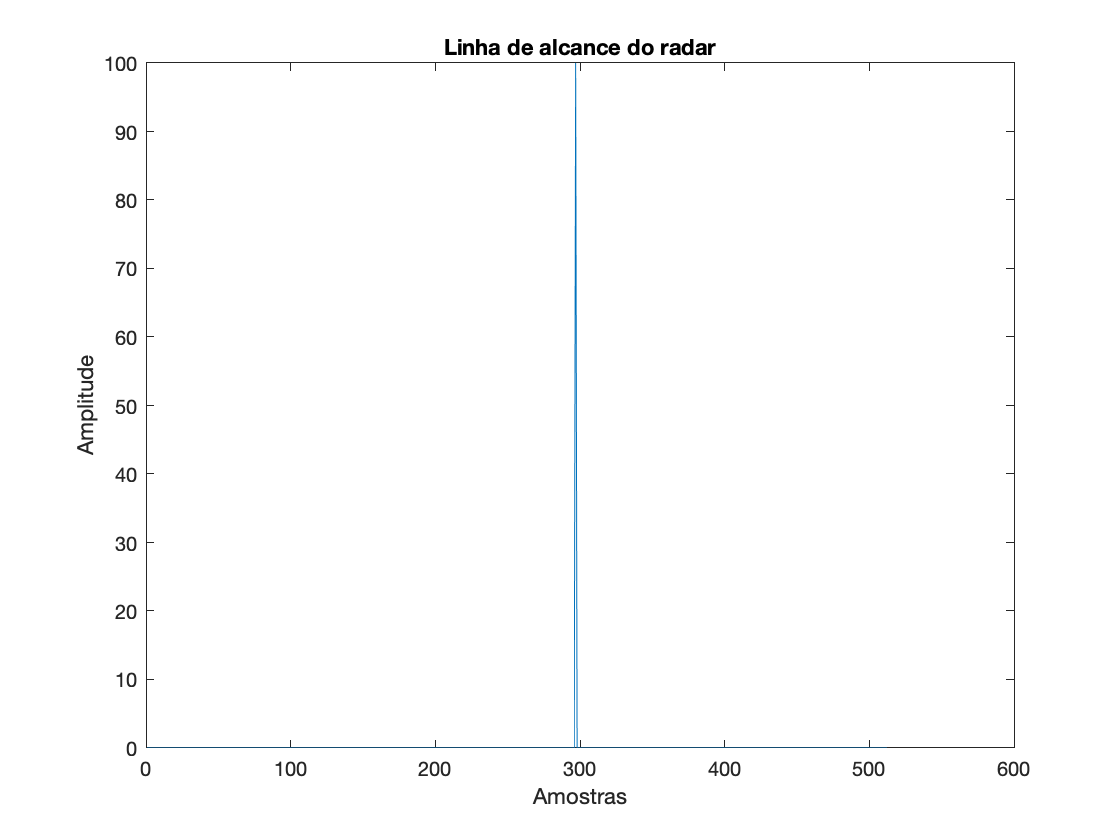

range = 370;  % Distância: radar <--> alvo
RCS = 100;
N = 512;                        % Número de amostras em alcance
c = physconst('Lightspeed');

deltaRange = c/samplingRate/2; %incremento de alcance

rangeLine2a =zeros(1,N);
rangeBin = round(range/deltaRange) +1;

rangeLine2a(rangeBin) = RCS;


figure
plot(rangeLine2a)
xlabel('Amostras')
ylabel('Amplitude')
title('Linha de alcance do radar')

**b)** Faça a convolução da linha de alcance do item **(a)** com o pulso modulado em frequência do **Exercício 1**, de forma que:

- O sinal resultante tenha 512 amostras;

- O pulso fique centrado na amostra correspondente ao alcance de visada direta do alvo (370 m).

Mostre a parte real e a parte imaginária da linha de alcance resultante.

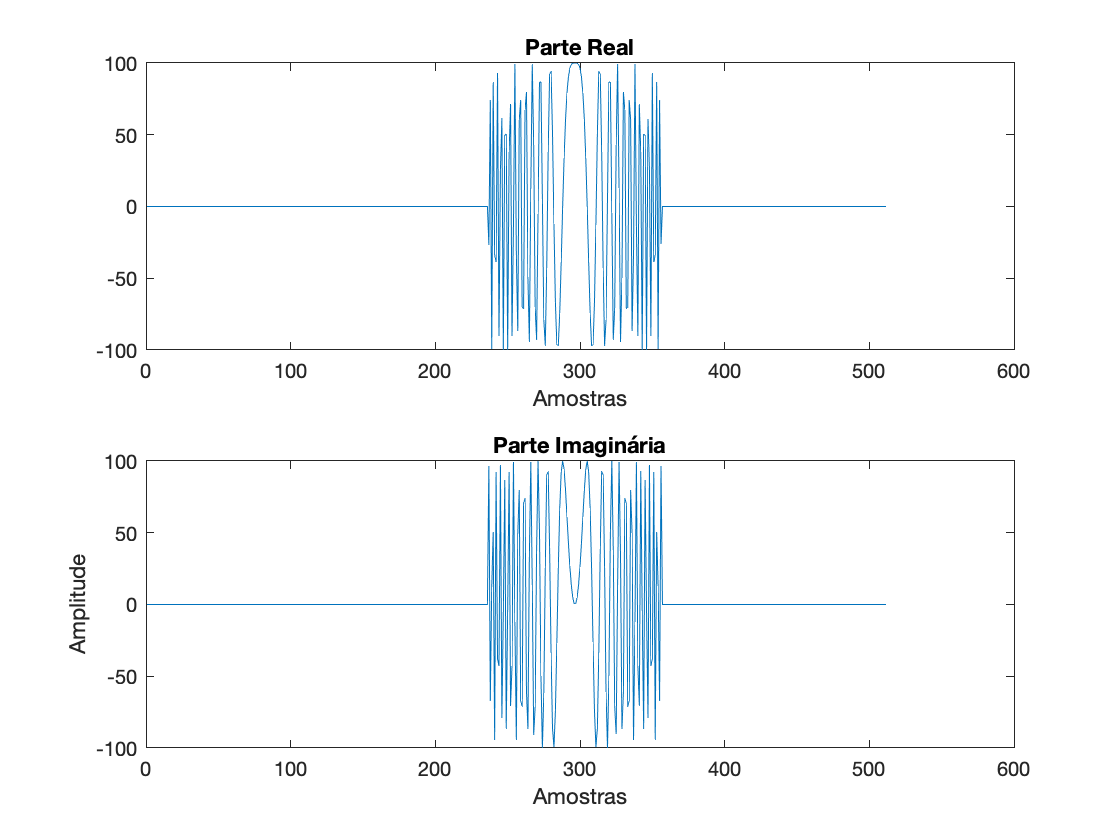

rangeLine2b = conv(rangeLine2a,chirp_,'same');

figure
subplot(2,1,1)
plot(real(rangeLine2b))
xlabel('Amostras')
title('Parte Real')

subplot(2,1,2)
plot(imag(rangeLine2b))
xlabel('Amostras')
ylabel('Amplitude')
title('Parte Imaginária')

**c) **O comprimento de onda central do radar é igual a 0,056 m. Refaça o item **(a)**, incluindo a fase do sinal de retorno, e mostre a magnitude e a fase da linha de alcance.

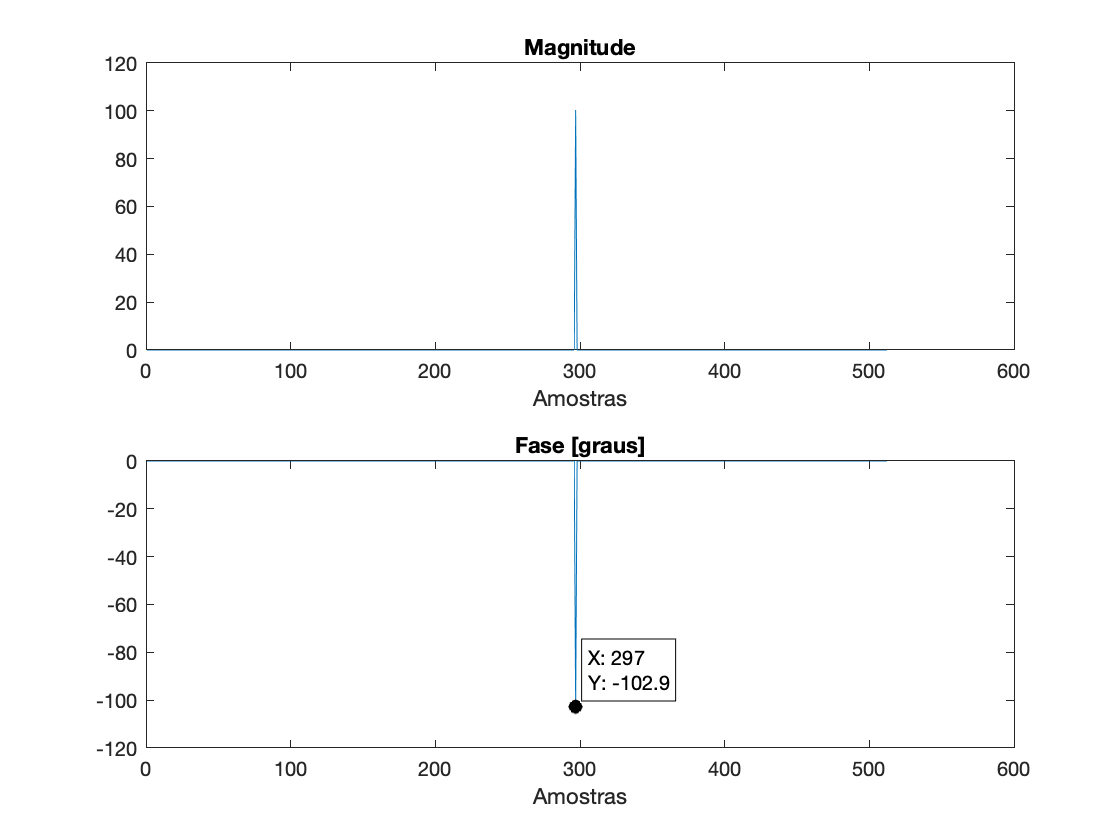

lambda = 0.056;

phi = -4*pi*range/lambda;

rangeLine2c = zeros(1,N);
rangeLine2c(rangeBin) = RCS*exp(1i*phi);

figure
subplot(2,1,1)
plot(abs(rangeLine2c))
xlabel('Amostras')
title('Magnitude')
subplot(2,1,2)
plot(rad2deg(angle(rangeLine2c)))
xlabel('Amostras')
title('Fase [graus]')

**d)** Faça a convolução da linha de alcance do item **(c)** com o pulso modulado em frequência do **Exercício 1**, de forma que:

- O sinal resultante tenha 512 amostras;

- O pulso fique centrado na amostra correspondente ao alcance de visada direta do alvo (370 m).

Mostre a parte real, a parte imaginária, a magnitude e a fase da linha de alcance resultante.

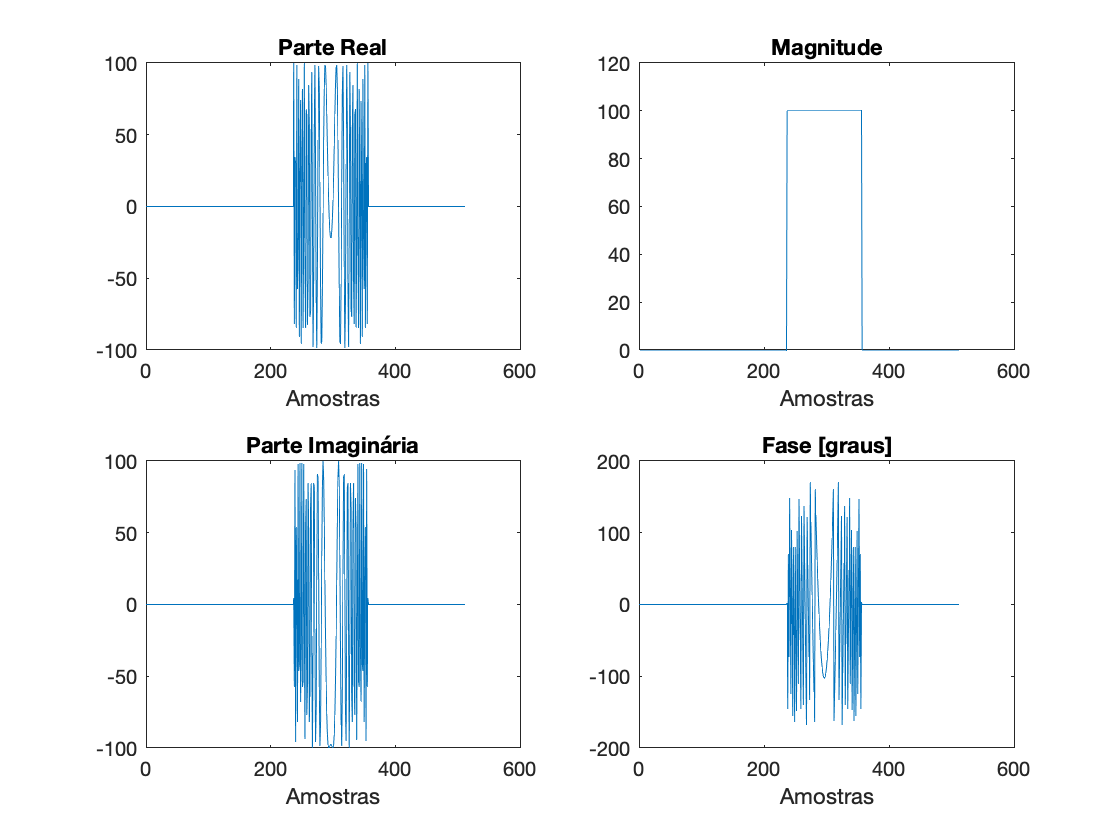

% Escreva seu código aqui
rangeLine2d = conv(rangeLine2c,chirp_,'same');

figure;
subplot(2,2,1)
plot(real(rangeLine2d))
xlabel('Amostras')
title('Parte Real')

subplot(2,2,3)
plot(imag(rangeLine2d))
xlabel('Amostras')
title('Parte Imaginária')

subplot(2,2,2)
plot(abs(rangeLine2d))
xlabel('Amostras')
title('Magnitude')

subplot(2,2,4)
plot(angle(rangeLine2d)*180/pi)
xlabel('Amostras')
title('Fase [graus]')

**Exercício 3**

Faça a correlação da linha de alcance encontrada no **Exercício 2(d)** com o pulso modulado em frequência do **Exercício 1**, conforme o diagrama abaixo:

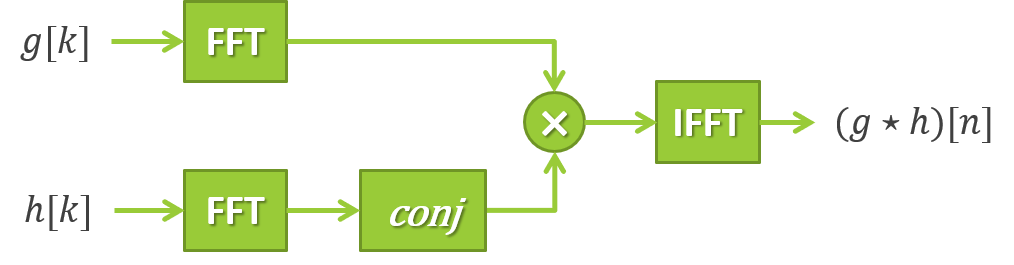

Considerações:

- As entradas `g[k]` e `h[k]` devem possuir o mesmo tamanho;

- O sinal de referência `h[k]` deve ser ajustado, usando o comando

**a) **Mostre a parte real e a parte imaginária do sinal de referência.

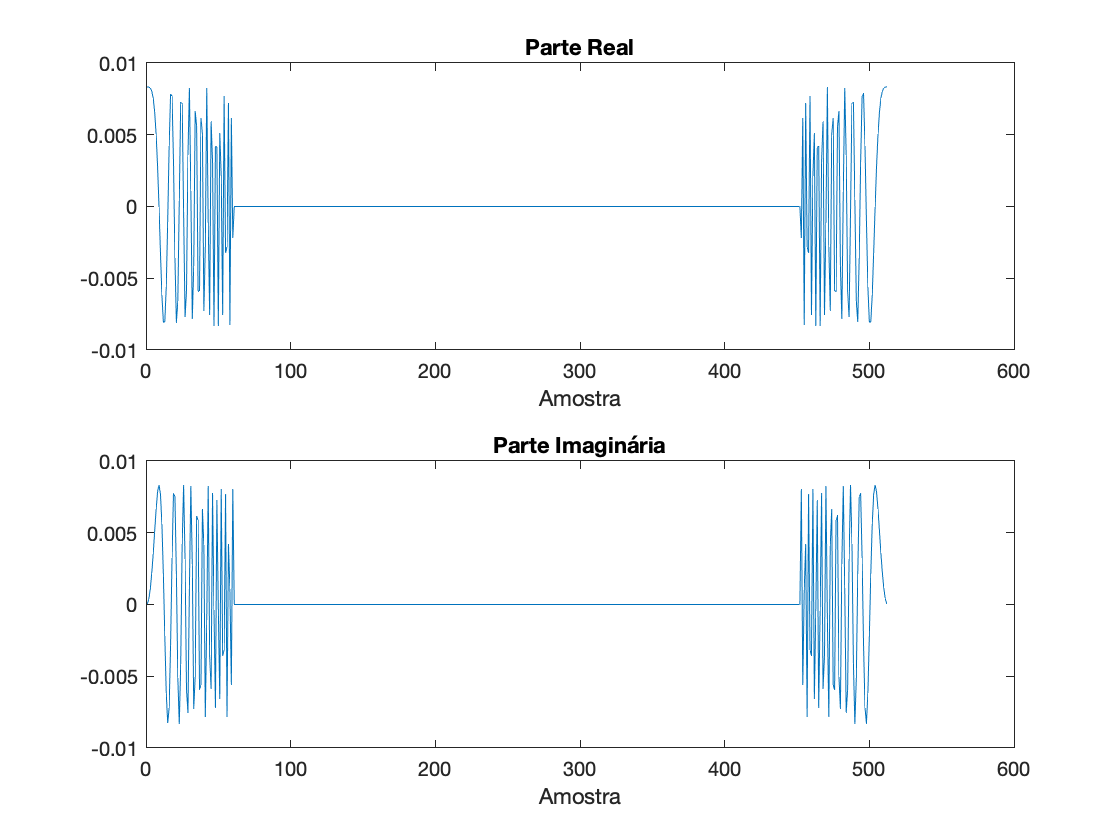

% Escreva seu código aqui
chirp_zp = [chirp_ zeros(1, N-M)];

shift = -floor(M/2);
reference3a = circshift(chirp_zp, shift)/M;



figure
subplot(2,1,1)
plot(real(reference3a))
xlabel('Amostra')
title('Parte Real')

subplot(2,1,2)

plot(imag(reference3a))
xlabel('Amostra')
title('Parte Imaginária')

**b)** Mostre a magnitude do sinal comprimido em alcance (resultado da correlação). O sinal de referência ainda necessita de algum ajuste? Qual? 

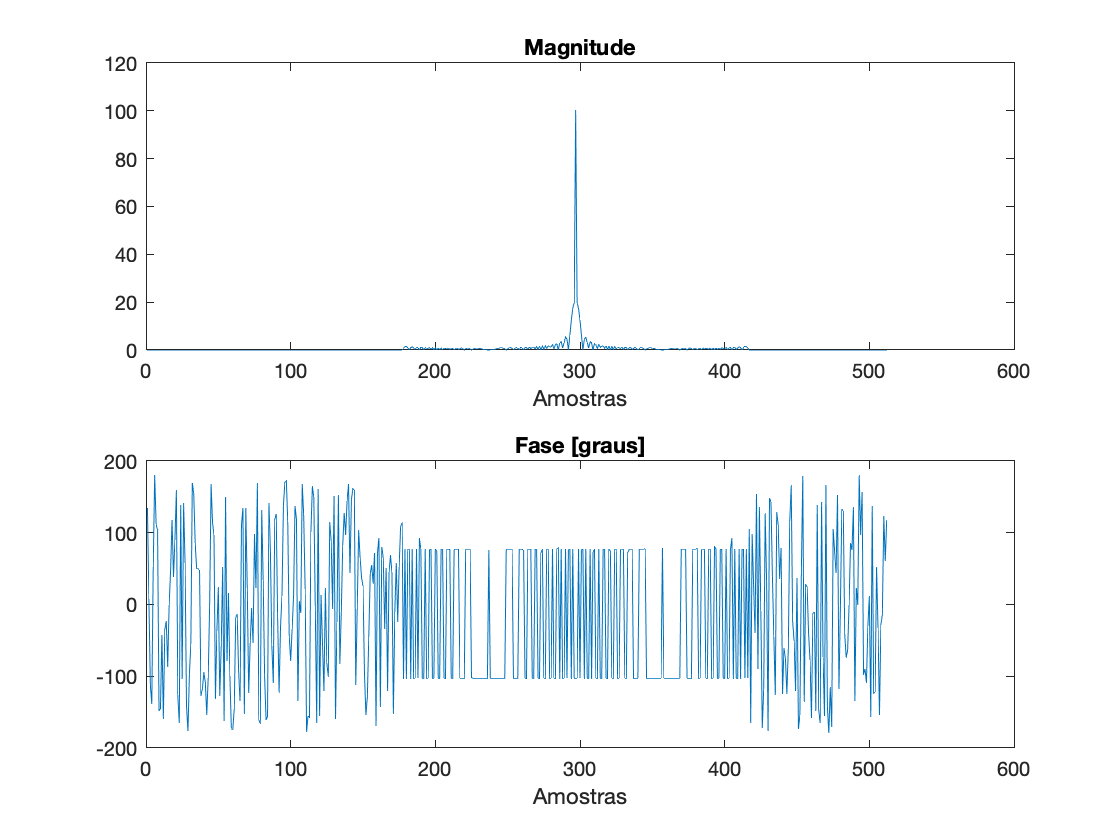

% Escreva seu código aqui
compressedSignal3b = ifft(fft(rangeLine2d) .* conj(fft(reference3a)));


figure
subplot(2,1,1)

plot(abs(compressedSignal3b))
xlabel('Amostras')
title('Magnitude')

subplot(2,1,2)

plot(angle((compressedSignal3b))*180/pi)
xlabel('Amostras')
title('Fase [graus]') 

**Exercício 4**

Uma possível solução para reduzir os lóbulos secundários é aplicar a função de janelamento de Hamming ao sinal de referência.

**a)** Crie uma janela de Hamming de mesma largura que a janela do pulso modulado em frequência do **Exercício 1**. Utilize uma das equações abaixo:


$$w\left\lbrack m\right\rbrack =0\ldotp 54-0\ldotp 46\mathrm{cos}\left(\frac{2\pi m}{M-1}\right),\;0\le m\le M-1$$



$$w\left\lbrack m\right\rbrack =0\ldotp 54+0\ldotp 46\cos \left(\frac{2\pi m}{M-1}\right),\;-\frac{M-1}{2}\le m\le \frac{M-1}{2}$$


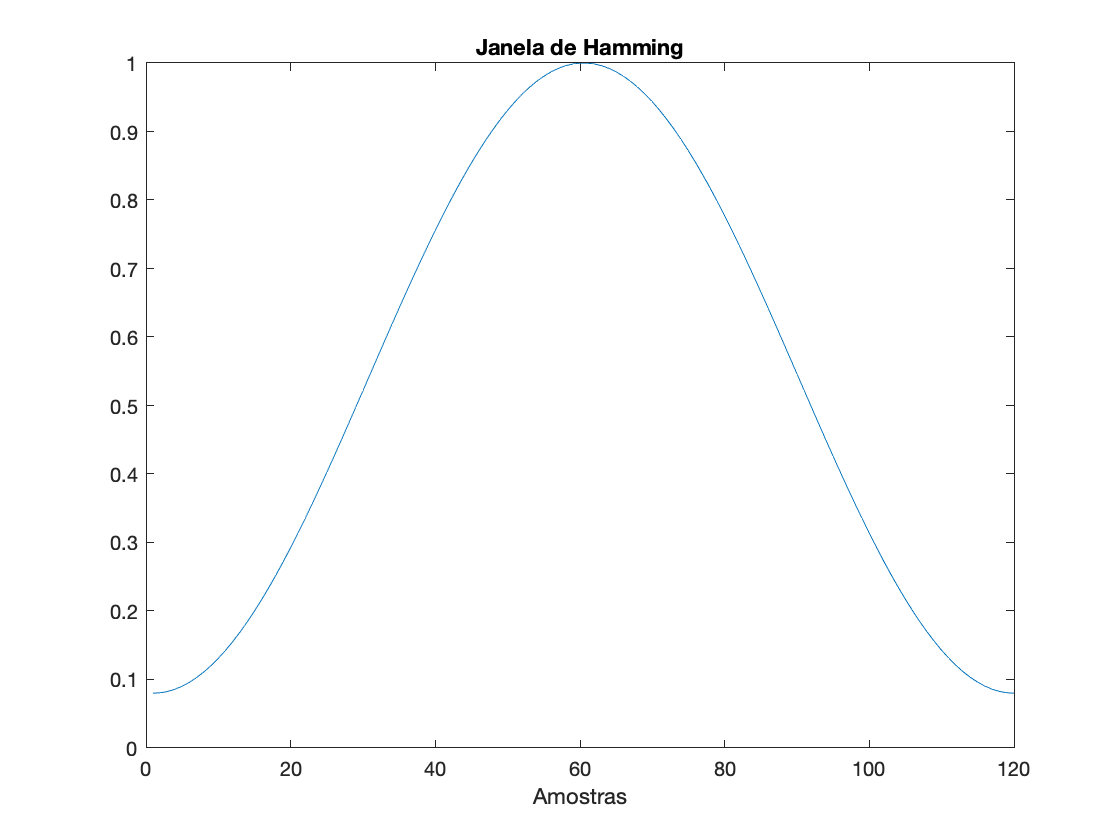

m = -(M-1)/2:(M-1)/2;
hamming = 0.54 + 0.46*cos(2*pi*m/(M-1));

figure
plot(hamming)
xlabel('Amostras')
title('Janela de Hamming')

**b)** Aplique a função de janelamento de Hamming ao pulso modulado em frequência para criar um novo sinal de referência.

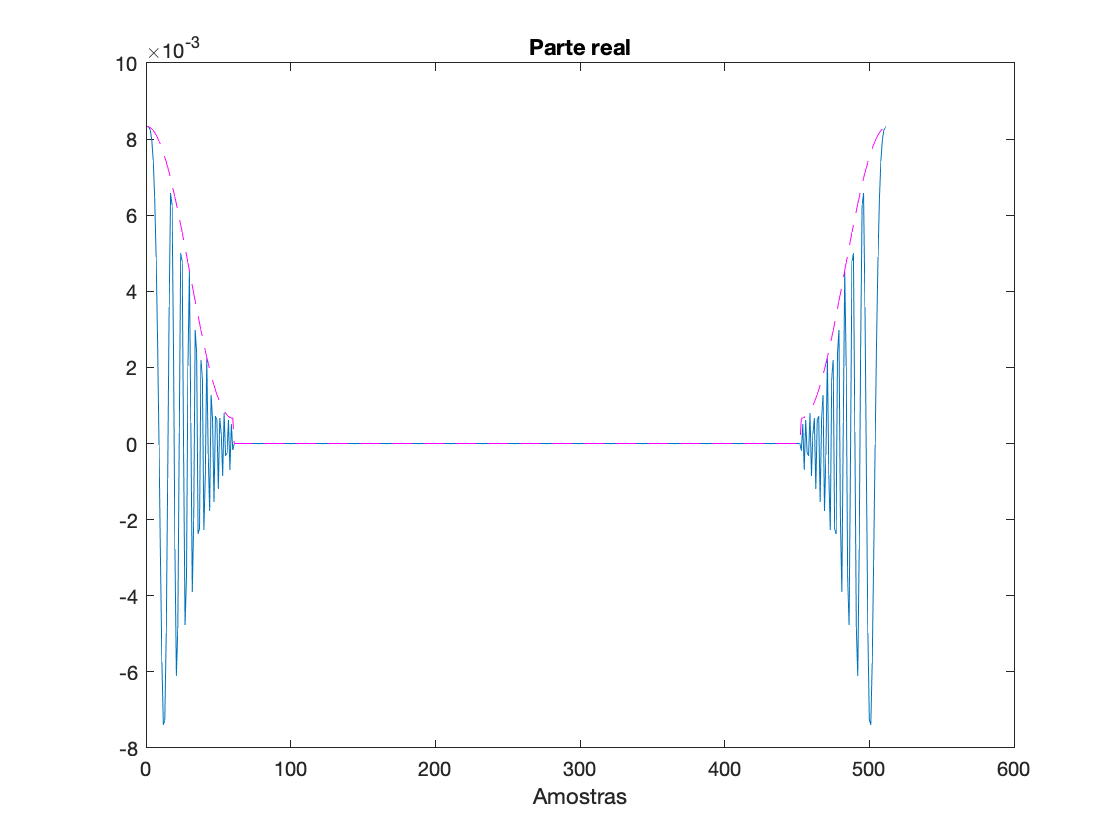

% Escreva seu código aqui
extendedHamming = [hamming zeros(1,N-M)];
shiftedHamming = circshift(extendedHamming,shift);

reference4b = reference3a.*shiftedHamming;

figure
plot(1:N,real(reference4b),1:N,shiftedHamming*abs(max(reference4b)),'m--')
xlabel('Amostras')
title('Parte real')

**c)** Faça a correlação da linha de alcance encontrada no **Exercício 2(d)** com o sinal de referência do item anterior. Compare com o resultado do **Exercício 3(b)**. 

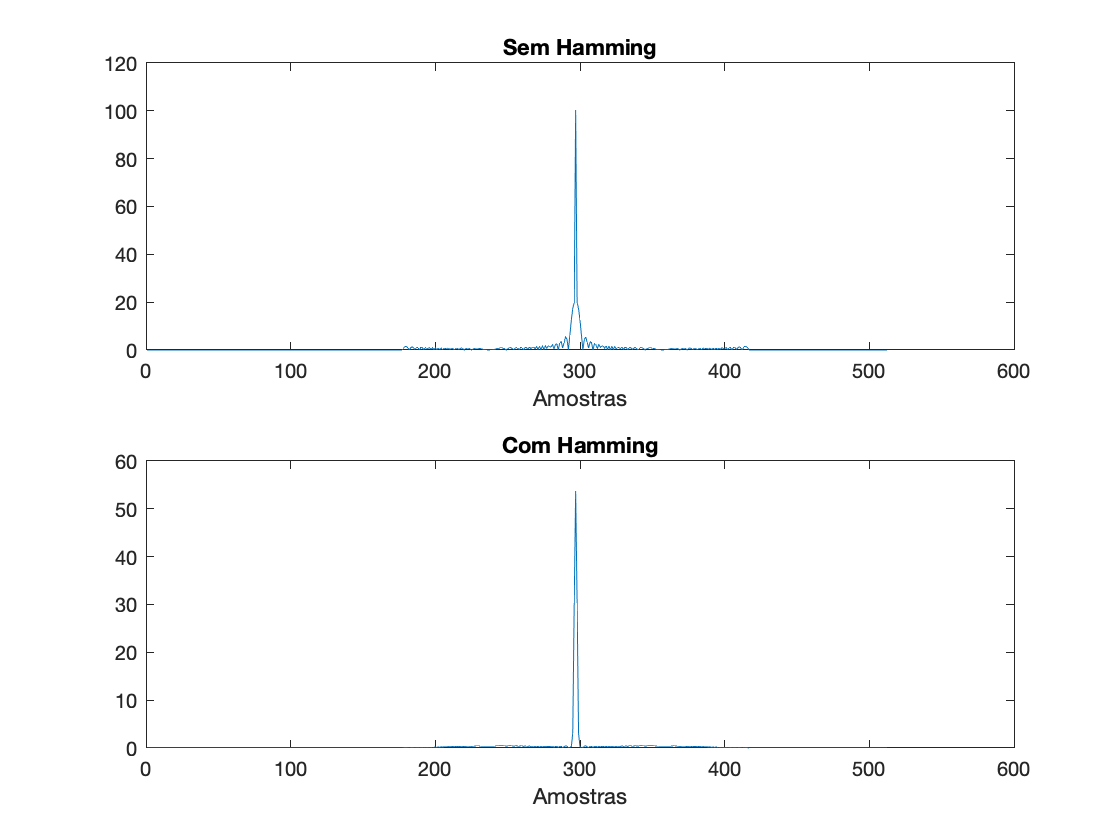

% Escreva seu código aqui
compressedSignal4c = ifft(fft(rangeLine2d) .* conj(fft(reference4b)));


figure
subplot(2,1,1)

plot(abs(compressedSignal3b))
xlabel('Amostras')
title('Sem Hamming')


subplot(2,1,2)
plot(abs(compressedSignal4c))
xlabel('Amostras')
title('Com Hamming')

# **TAREFA - Entrega até terça, 13/10/2020, às 24h**

A tarefa consiste de duas partes:

- Dados brutos sem compressão em alcance, que devem ser gerados conforme as tarefas propostas nas Aulas Práticas 1 e 2, substituindo o pulso gaussiano por um pulso modulado em frequência de 1 μs de duração e 100 MHz de banda, e cuja frequência varia linearmente com o tempo; 

- Dados brutos com compressão em alcance, aplicando um janelamento de hamming

Orientações:

- Escreva os códigos em arquivo de script chamado *dadosBrutos_1ºNome_RA.m*;

- Escreva separadamente as linhas de código referentes a cada parte da tarefa e ao pulso modulado por frequência;

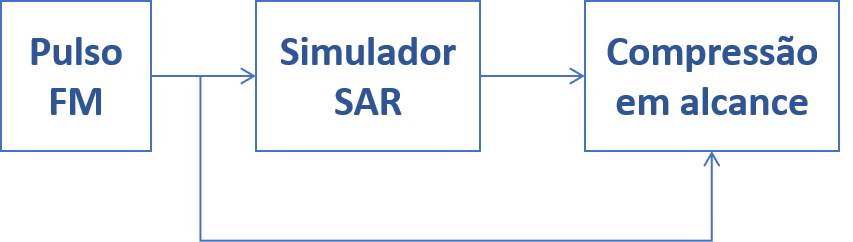

- Escolha nomes significativos para as variáveis, de acordo com suas funcionalidades;

- Use comentários para facilitar a compreensão do código, especialmente se você utilizar soluções diferentes das apresentadas em aula.